clear
load('2.mat')
shapeit_data.C.block

ans = 1×3 struct array with fields:
    type
    param


C = shapeit_data.C_tf %controller

C =
 
   0.02653 s^3 + 0.6747 s^2 + 2879 s + 5.42e04
  ---------------------------------------------
  0.005305 s^3 + 2.747 s^2 + 904.3 s + 1.084e05
 
Continuous-time transfer function.
Model Properties


P = shapeit_data.P.sys %system

P =
 
            3.002e08
  ----------------------------
  s^4 + 3.943 s^3 + 108000 s^2
 
Continuous-time transfer function.
Model Properties



de = 1/(1+C*P)

de =
 
              0.005305 s^7 + 2.768 s^6 + 1488 s^5 + 4.086e05 s^4 + 9.809e07 s^3 + 1.171e10 s^2
  --------------------------------------------------------------------------------------------------------
  0.005305 s^7 + 2.768 s^6 + 1488 s^5 + 4.086e05 s^4 + 1.061e08 s^3 + 1.191e10 s^2 + 8.642e11 s + 1.627e13
 
Continuous-time transfer function.


t = [0:0.01:10];
u = sin(2*2*pi*t)

u =             0   1.2533e-01   2.4869e-01   3.6812e-01   4.8175e-01   5.8779e-01   6.8455e-01   7.7051e-01   8.4433e-01   9.0483e-01   9.5106e-01   9.8229e-01   9.9803e-01   9.9803e-01   9.8229e-01   9.5106e-01   9.0483e-01   8.4433e-01   7.7051e-01   6.8455e-01   5.8779e-01   4.8175e-01   3.6812e-01   2.4869e-01   1.2533e-01   1.2246e-16  -1.2533e-01  -2.4869e-01  -3.6812e-01  -4.8175e-01  -5.8779e-01  -6.8455e-01  -7.7051e-01  -8.4433e-01  -9.0483e-01  -9.5106e-01  -9.8229e-01  -9.9803e-01  -9.9803e-01  -9.8229e-01  -9.5106e-01  -9.0483e-01  -8.4433e-01  -7.7051e-01  -6.8455e-01  -5.8779e-01  -4.8175e-01  -3.6812e-01  -2.4869e-01  -1.2533e-01


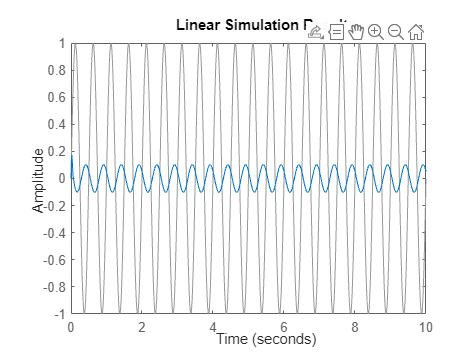

lsim(de,u,t)

load('2-2.mat')
C = shapeit_data.C_tf %controller

C =
 
   22.3 s^3 + 4768 s^2 + 2.41e06 s + 4.935e08
  --------------------------------------------
  0.0005305 s^3 + 1.333 s^2 + 5864 s + 9.87e06
 
Continuous-time transfer function.
Model Properties


P = shapeit_data.P.sys %system

P =
 
            3.002e08
  ----------------------------
  s^4 + 3.943 s^3 + 108000 s^2
 
Continuous-time transfer function.
Model Properties


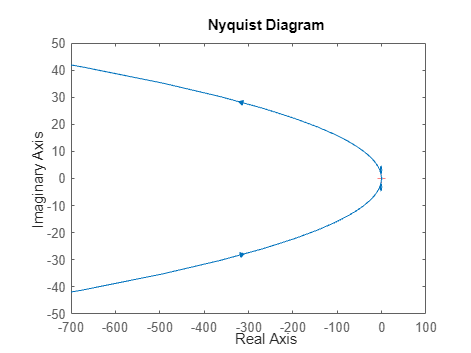


nyquist(C*P)